# Machine Learning Classifier to Predict Alzheimer's Disease from Microarray Data

Authors: Kristen Norray, Zeal Jinwala, Henry Hollis

### Process Data in R

Here we use GEO_z_norm.R to read in geo files from GEO database. We

find the intersect of the genes in all the geo series and return them in csv files

of dimensions (samples X genes). We also return the metadata for each series.

warning('off','all');
datadir = bmes.datadir();
%run Rscript if files not already present

if ~all(isfile({[datadir '/GSE63060_z_intersectGenes.csv'] ,...
        [datadir '/GSE63061_z_intersectGenes.csv'], ...
        [datadir '/GSE44772_z_intersectGenes.csv']}))
%If not working, try replacing Rexe() with path to Rscript.exe, as described in README.md 
system([Rexe() ' ./Rscripts/GEO_z_norm_de.R ' datadir ]);
end

Bioconductor version 3.15 (BiocManager 1.30.18), R 4.2.0 (2022-04-22)
Old packages: 'dbplyr', 'MASS'
Warning message:
package(s) not installed when version(s) same as current; use `force = TRUE` to
  re-install: 'GEOquery' 
Loading required package: Biobase
Loading required package: BiocGenerics

Attaching package: ‘BiocGenerics’

The following objects are masked from ‘package:stats’:

    IQR, mad, sd, var, xtabs

The following objects are masked from ‘package:base’:

    anyDuplicated, append, as.data.frame, basename, cbind, colnames,
    dirname, do.call, duplicated, eval, evalq, Filter, Find, get, grep,
    grepl, intersect, is.unsorted, lapply, Map, mapply, match, mget,
    order, paste, pmax, pmax.int, pmin, pmin.int, Position, rank,
    rbind, Reduce, rownames, sapply, setdiff, sort, table, tapply,
    union, unique, unsplit, which.max, which.min

Welcome to Bioconductor

    Vignettes contain introductory material; view with
    'browseVignettes()'. To cite Bioconductor, see
  

### Differential Expression Analysis

system([Rexe() ' ./Rscripts/venn_diagram_de_genes.R ' datadir]);

also installing the dependencies ‘formatR’, ‘lambda.r’, ‘futile.options’, ‘futile.logger’

trying URL 'http://cran.us.r-project.org/bin/macosx/contrib/4.2/formatR_1.12.tgz'
Content type 'application/x-gzip' length 148775 bytes (145 KB)
downloaded 145 KB

trying URL 'http://cran.us.r-project.org/bin/macosx/contrib/4.2/lambda.r_1.2.4.tgz'
Content type 'application/x-gzip' length 110070 bytes (107 KB)
downloaded 107 KB

trying URL 'http://cran.us.r-project.org/bin/macosx/contrib/4.2/futile.options_1.0.1.tgz'
Content type 'application/x-gzip' length 18213 bytes (17 KB)
downloaded 17 KB

trying URL 'http://cran.us.r-project.org/bin/macosx/contrib/4.2/futile.logger_1.4.3.tgz'
Content type 'application/x-gzip' length 95641 bytes (93 KB)
downloaded 93 KB

trying URL 'http://cran.us.r-project.o

**Let's see the overlap of differentially expressed genes in all datasets:**

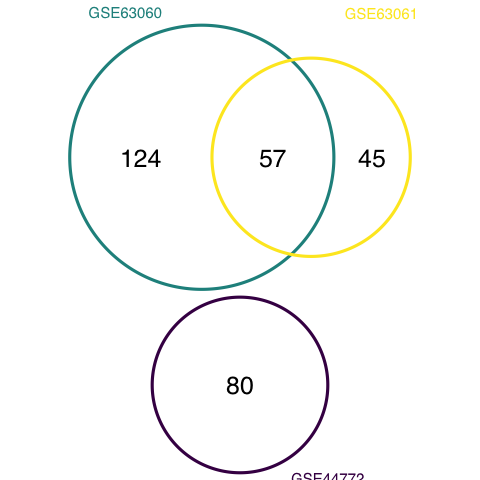

**Next, we uploaded genes found differentially expressed between AD and CTL group for each dataset**

**to NCBI's DAVID. We saved the results tp ../Enrichment_results**

**Here we take those results and visualize them:**

% only run if pngs not in datadir
if ~all(isfile({[datadir '/GSE63060_DAVID_results.txt.png'] ,...
        [datadir '/GSE63061_DAVID_results.txt.png'], ...
        [datadir '/GSE44772_DAVID_results.txt.png']}))
system([Rexe() ' ./Rscripts/enrich_script.R ' pwd '/Enrichment_results/ ' datadir]);
end

Bioconductor version 3.15 (BiocManager 1.30.18), R 4.2.0 (2022-04-22)
Installing package(s) 'rrvgo'
also installing the dependencies ‘bitops’, ‘zlibbioc’, ‘RCurl’, ‘GenomeInfoDbData’, ‘XVector’, ‘GenomeInfoDb’, ‘memoise’, ‘plogr’, ‘png’, ‘Biostrings’, ‘Rcpp’, ‘IRanges’, ‘RSQLite’, ‘S4Vectors’, ‘KEGGREST’, ‘gridBase’, ‘igraph’, ‘NLP’, ‘slam’, ‘BH’, ‘httpuv’, ‘xtable’, ‘fontawesome’, ‘sourcetools’, ‘later’, ‘promises’, ‘commonmark’, ‘cachem’, ‘GOSemSim’, ‘AnnotationDbi’, ‘GO.db’, ‘pheatmap’, ‘ggrepel’, ‘treemap’, ‘tm’, ‘wordcloud’, ‘shiny’

trying URL 'https://cloud.r-project.org/bin/macosx/contrib/4.2/bitops_1.0-7.tgz'
Content type 'application/x-gzip' length 29377 bytes (28 KB)
downloaded 28 KB

trying URL 'https://bioconductor.org/packages/3.15/bioc/bin/macosx/contrib/4.2/zlibbioc_1.42.0.tgz'
Content type 'application/x-gzip' length 61876 bytes (60 KB)
downloaded 60 KB

trying URL 'ht

### 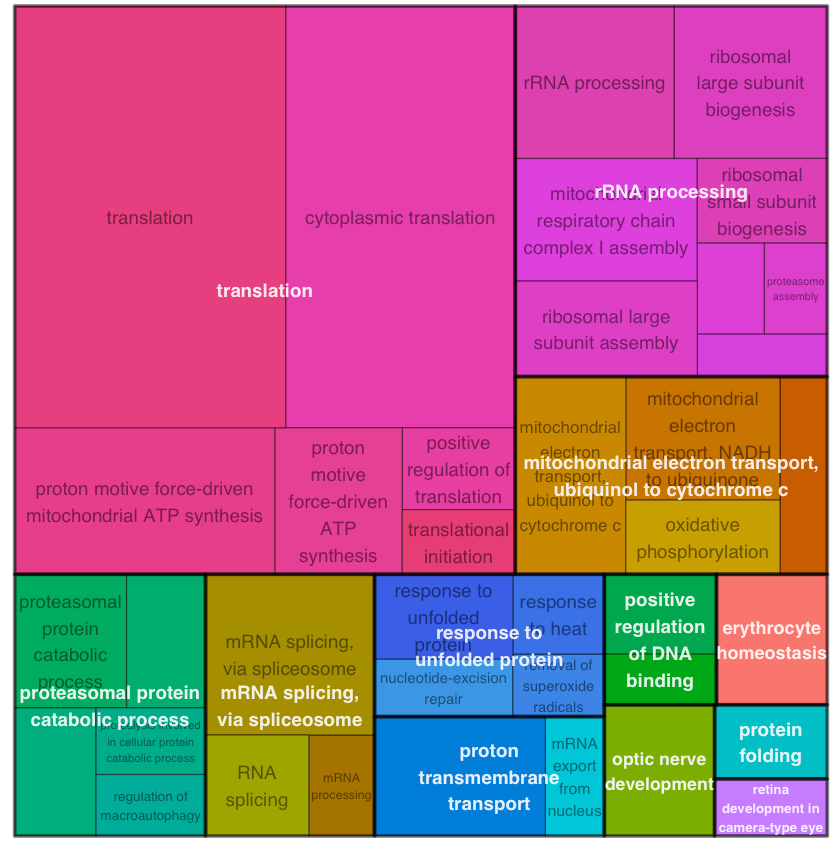

### 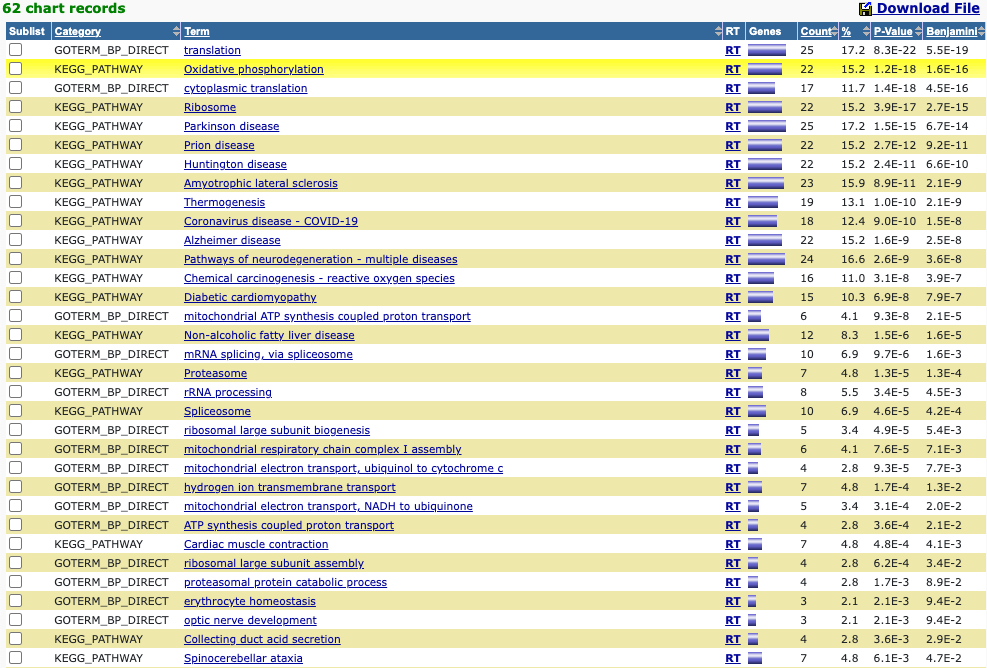

### Read in files processed in R, this is the training data and metadata:

[~, GSE63060_meta, GSE63060_num, ~, probes] = read_in_data_meta(datadir, 'GSE63060');
[~, GSE63061_meta, GSE63061_num] = read_in_data_meta(datadir, 'GSE63061');
[~, GSE44772_meta, GSE44772_num] = read_in_data_meta(datadir, 'GSE44772');

%concat the two separate training sets into one:
all_data = [GSE63061_num; GSE63060_num; GSE44772_num];

%get the labels from the metadata
tmp_labels = [GSE63061_meta; GSE63060_meta];
tmp_labels = tmp_labels{:, 'characteristics_ch1'};

%get column of GSE44772 metadata corresponding to condition
tmp_labels2 = GSE44772_meta(:, 4);
tmp_labels2 = regexprep(table2cell(tmp_labels2(:, 1)),'disease: ','');

labels = [tmp_labels; tmp_labels2];

Let's see the current disease annotations (labels)

unique(labels)

We remove the "OTHER, " "borderline MCI," "MCI to CTL, " and "CTL to AD" cases (only ~8 subjects).

rm =strcmp(labels, 'status: MCI to CTL') |...
    strcmp(labels, 'status: CTL to AD') |...
    strcmp(labels, 'status: borderline MCI') |... %remove these
    strcmp(labels, 'status: OTHER');

labels =  labels(~rm);   %perform removal in labels
all_data = all_data(~rm, :);     %perform removal in data

%remove 'status: ' in labels 
labels = regexprep(labels,'status: ','');
%replace CTL with N
labels = regexprep(labels,'AD','A');
labels = regexprep(labels,'CTL','N');

Now let's see the annotations:

unique(labels)


% test train split (train: 70%, test: 30%)
%automatically stratifies by class so 
%train and test sets have roughly same proportion of class
cv = cvpartition(labels,'HoldOut',0.3);
idx = cv.test;
% Separate to training and test data
Train_data = all_data(~idx,:);
Train_labels = labels(~idx, :);

Test_data  = all_data(idx,:);
Test_labels = labels(idx, :);

### Train a classifier on CTL vs AD subjects,

### and on CTL vs MCI subjects:

%First, we retain only CTL and AD train labels and data:
[CTL_AD_Train_labs, rm] = get_binary_labels(Train_labels, 'N', 'A');
CTL_AD_Train_data = Train_data(~rm, :);

%repeat for CTL vs MCI train labels and data
[CTL_MCI_Train_labs, rm] = get_binary_labels(Train_labels, 'N', 'MCI');
CTL_MCI_Train_data = Train_data(~rm, :);

%%%%%% Test data and labels %%%%%

%First, we retain only CTL and AD test labels and data:
[CTL_AD_Test_labs, rm] = get_binary_labels(Test_labels, 'N', 'A');
CTL_AD_Test_data = Test_data(~rm, :);

%repeat for CTL vs MCI test labels and data
[CTL_MCI_Test_labs, rm] = get_binary_labels(Test_labels, 'N', 'MCI');
CTL_MCI_Test_data = Test_data(~rm, :);


### Feature selection and cross validation:

cv_AD = cvpartition(CTL_AD_Train_labs,'k',10);   %call 10-fold cross val
cv_MCI = cvpartition(CTL_MCI_Train_labs,'k',10);
if isfile('./MATLAB_vars/ADselectedfeatures.mat')
	load('./MATLAB_vars/ADselectedfeatures.mat');
else
  [~,selected_AD] = perform_cv_fs(CTL_AD_Train_data, CTL_AD_Train_labs, cv_AD);
 save('./MATLAB_vars/ADselectedfeatures.mat', 'selected_AD');
end

[cv_AD_Error, selected_AD, model_CTL_AD]= perform_cv_fs(CTL_AD_Train_data, CTL_AD_Train_labs, cv_AD,selected_AD);
fprintf('10-fold CTL-AD acc: %.3f',1 - sum(cv_AD_Error)/numel(CTL_AD_Train_labs))

if isfile('./MATLAB_vars/MCIselectedfeatures.mat')
	load('./MATLAB_vars/MCIselectedfeatures.mat');
else
  [~, selected_MCI] = perform_cv_fs(CTL_MCI_Train_data, CTL_MCI_Train_labs, cv_MCI);
 save('./MATLAB_vars/MCIselectedfeatures.mat', 'selected_MCI');
end

[cv_MCI_Error, selected_MCI, model_CTL_MCI] = perform_cv_fs(CTL_MCI_Train_data, CTL_MCI_Train_labs, cv_MCI,selected_MCI);
fprintf('10-fold CTL-MCI acc: %.3f',1 - sum(cv_MCI_Error)/numel(CTL_MCI_Train_labs))

### Accuracy on AD classification on left out test set:

AD_preds = predict(model_CTL_AD, CTL_AD_Test_data(:,selected_AD));
AD_accuracy = sum(AD_preds == CTL_AD_Test_labs)/numel(CTL_AD_Test_labs)
C = confusionmat(CTL_AD_Test_labs, AD_preds);
confusionchart(C, {'CTL', 'AD'})

### Accuracy on MCI classification on left out test set:

MCI_preds = predict(model_CTL_MCI, CTL_MCI_Test_data(:,selected_MCI));
MCI_accuracy = sum(MCI_preds == CTL_MCI_Test_labs)/numel(CTL_MCI_Test_labs)
C = confusionmat(CTL_MCI_Test_labs, MCI_preds);
confusionchart(C, {'CTL', 'MCI'})

### Selected features genes

% index of selected genes shifted left 1 b/c we removed the
% first column in our training data (column of subject IDs)
selected_genes = [find(selected_MCI), find(selected_AD)];
selected_probes = probes(2:end);
selected_probes{selected_genes}